fp=0.2KHz,Rp=1dB,fs=0.3KHz,As=25dB,T

=1ms;

分别用脉冲响应不变法及双线性变换法设

计一Butterworth数字低通滤波器

观察所设计数

字滤波器的幅频特性曲线,

记录带宽和衰减量

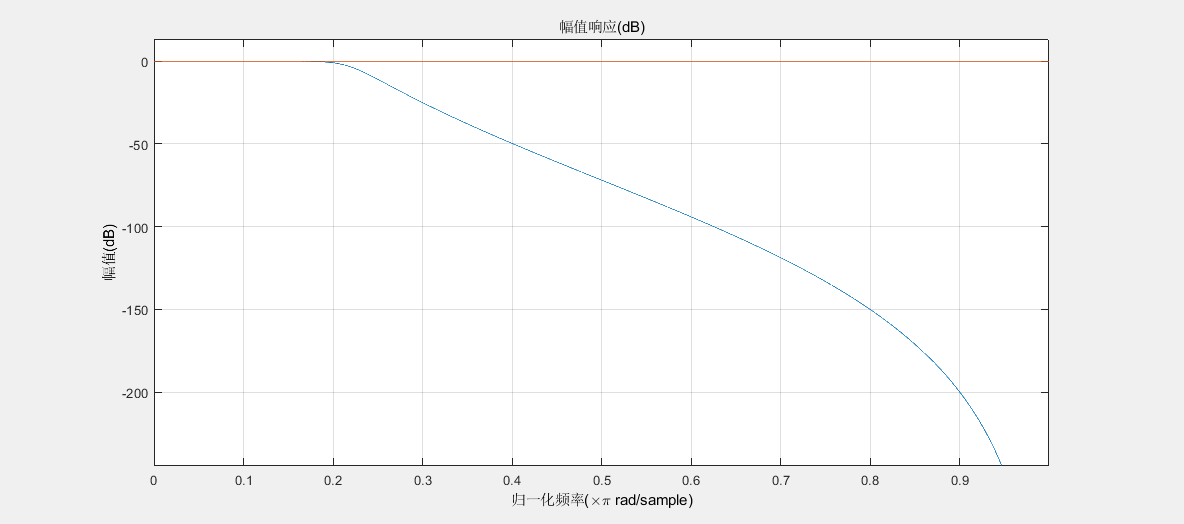

[n,Wn] = buttord(0.2,0.3,1,25);
[b,a] = butter(n,Wn);
fvtool(b,a,1000,1000)

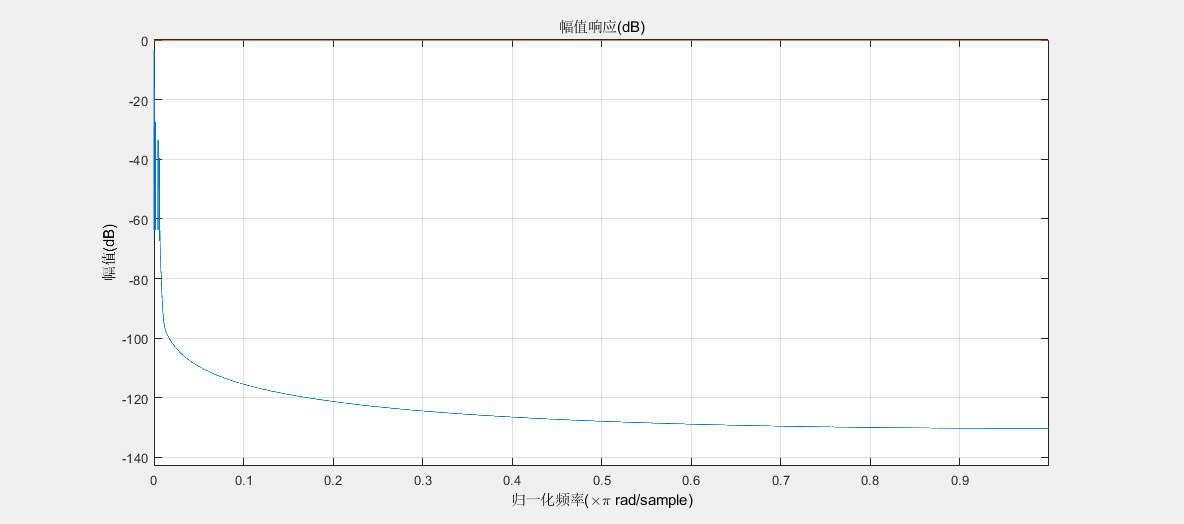

[iimB,iimA] = impinvar(b,a,1000);
fvtool(iimB,iimA,1000,1000)

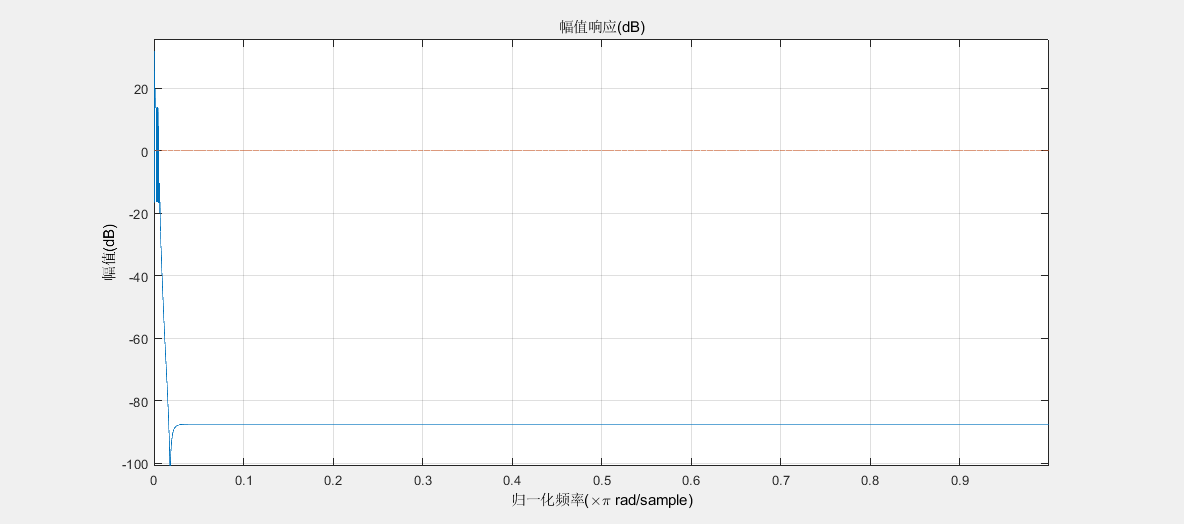

[blB,blA] = bilinear(b,a,1000);
fvtool(blB,blA,1000,1000)